# **MATLAB-(Intermediate- Advance Level)**

**sign( )**

A=5;
B=-13;
sign(A)

ans = 1

sign(B)

ans = -1

prod(1:10)

ans = 3628800

factorial(10)

ans = 3628800

randi(10,[1,10])

ans =      2    10    10     5     9     2     5    10     8    10


**rand**

geberate no. between 0-1

rand

ans = 0.5308

rand

ans = 0.7792

rand

ans = 0.9340

**randi(N)** it will generate number between 1to N

randi(6)

ans = 2

randi(25)

ans = 14

**randi([n1,n2])** it will generate random number between n1 to n2

randi([13,28])

ans = 24

randi([4,6])

ans = 5

rand(n) it will create a random n*n matrix (all element between o-1)

rand(3)

ans =     0.1067    0.7749    0.0844
    0.9619    0.8173    0.3998
    0.0046    0.8687    0.2599


rand(4)

ans =     0.8001    0.2638    0.5797    0.6221
    0.4314    0.1455    0.5499    0.3510
    0.9106    0.1361    0.1450    0.5132
    0.1818    0.8693    0.8530    0.4018


## Relational Expressions & Logical Operators

**Relational Expressions**

A>B

A>B

A<=B

A>=B

A==B

A~=B

 **Logical Operators**

||    or

&&    and

~      not

A=5;
B=-6;
A>B

ans = logical
   1


A~=B

ans = logical
   1


A<B

ans = logical
   0


A<=B

ans = logical
   0


A>=B

ans = logical
   1


class(ans)

ans = 'logical'

Note- to check typr of operation, **class(ans)**

A==B

ans = logical
   0


class(ans)

ans = 'logical'

## Perform Doc Command 

to search topic and tools and study.

# **Working with Files**

% working with xlsheet

%working with text file


# **Matrix**

## Create diognal Matrix

A=[1 2 3;2 5 9;9 5 1]

A =      1     2     3
     2     5     9
     9     5     1


**reshape**

A=[1:16]

A =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16


help reshape

 reshape Reshape array.
    reshape(X,M,N) or reshape(X,[M,N]) returns the M-by-N matrix 
    whose elements are taken columnwise from X. An error results 
    if X does not have M*N elements.
 
    reshape(X,M,N,P,...) or reshape(X,[M,N,P,...]) returns an 
    N-D array with the same elements as X but reshaped to have 
    the size M-by-N-by-P-by-.... The product of the specified
    dimensions, M*N*P*..., must be the same as NUMEL(X).
 
    reshape(X,...,[],...) calculates the length of the dimension
    represented by [], such that the product of the dimensions 
    equals NUMEL(X). The value of NUMEL(X) must be evenly divisible 
    by the product of the specified dimensions. You can use only one 
    occurrence of [].
 
    See also squeeze, shiftdim, colon.

    

reshape(A,[4,4])

ans =      1     5     9    13
     2     6    10    14
     3     7    11    15
     4     8    12    16


reshape(A,4,4)

ans =      1     5     9    13
     2     6    10    14
     3     7    11    15
     4     8    12    16


A=[1:16]

A =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16


reshape(A,8,2)

ans =      1     9
     2    10
     3    11
     4    12
     5    13
     6    14
     7    15
     8    16



reshape(A,2,8)

ans =      1     3     5     7     9    11    13    15
     2     4     6     8    10    12    14    16


reshape(A,[2],[8])

ans =      1     3     5     7     9    11    13    15
     2     4     6     8    10    12    14    16


reshape(A,[2,8])

ans =      1     3     5     7     9    11    13    15
     2     4     6     8    10    12    14    16


A=[1:16];
% create matrix by only mentioning row or column
reshape(A,[],8)

ans =      1     3     5     7     9    11    13    15
     2     4     6     8    10    12    14    16


reshape(A,2,[])

ans =      1     3     5     7     9    11    13    15
     2     4     6     8    10    12    14    16


**diag(A)- **it works in two ways

A=reshape(1:16,[4],[])

A =      1     5     9    13
     2     6    10    14
     3     7    11    15
     4     8    12    16


B=[A(1,1) A(2,2) A(3,3) A(4,4)]

B =      1     6    11    16


B=[A(1,1) A(2,2) A(3,3) A(4,4)]'

B =      1
     6
    11
    16


% or to diagonal element
diag(A)

ans =      1
     6
    11
    16


C=diag(A)

C =      1
     6
    11
    16


diag(C)

ans =      1     0     0     0
     0     6     0     0
     0     0    11     0
     0     0     0    16


D=[1 5 8 9 10 5]

D =      1     5     8     9    10     5


diag(D)

ans =      1     0     0     0     0     0
     0     5     0     0     0     0
     0     0     8     0     0     0
     0     0     0     9     0     0
     0     0     0     0    10     0
     0     0     0     0     0     5


A=[1 2 3 4 6 5;4 5 6 2 5  6;9 5 1 7 5 3;3 5 7 1 5 9]

A =      1     2     3     4     6     5
     4     5     6     2     5     6
     9     5     1     7     5     3
     3     5     7     1     5     9


diag(A)

ans =      1
     5
     1
     1


diag(diag(A))

ans =      1     0     0     0
     0     5     0     0
     0     0     1     0
     0     0     0     1


A=reshape(1:16,[4],[])

A =      1     5     9    13
     2     6    10    14
     3     7    11    15
     4     8    12    16


%to make diagonal element zero
B=A-diag(diag(A))

B =      0     5     9    13
     2     0    10    14
     3     7     0    15
     4     8    12     0


**floor-** to get rid of digits after the points

A=reshape(1:16,[4],[]);
%symmetric matrix
(A+A')/2

ans =     1.0000    3.5000    6.0000    8.5000
    3.5000    6.0000    8.5000   11.0000
    6.0000    8.5000   11.0000   13.5000
    8.5000   11.0000   13.5000   16.0000


%antisymmetric matrix
(A-A')/2

ans =          0    1.5000    3.0000    4.5000
   -1.5000         0    1.5000    3.0000
   -3.0000   -1.5000         0    1.5000
   -4.5000   -3.0000   -1.5000         0


%to get rid of digit after the point
floor((A+A')/2)

ans =      1     3     6     8
     3     6     8    11
     6     8    11    13
     8    11    13    16


floor((A-A')/2)

ans =      0     1     3     4
    -2     0     1     3
    -3    -2     0     1
    -5    -3    -2     0


A=randi([10,100],6,6)

A =     66    93    16    61    38    72
    53    36    14    52    58    78
    42    78    58    11    25    50
    85    78    80    40    64    17
    63    44    94    24    33    30
    60    61    21    82    69    93


B=floor((A+A')/2)

B =     66    73    29    73    50    66
    73    36    46    65    51    69
    29    46    58    45    59    35
    73    65    45    40    44    49
    50    51    59    44    33    49
    66    69    35    49    49    93


## extract elements in Matlab

A=(reshape(1:9,[3],[]))'

A =      1     2     3
     4     5     6
     7     8     9


A(:)

ans =      1
     4
     7
     2
     5
     8
     3
     6
     9


A(:,:)

ans =      1     2     3
     4     5     6
     7     8     9


A(:)'

ans =      1     4     7     2     5     8     3     6     9


## create a Matrix Placeholder

A=[1 2 3;4 5 6;7 8 9]

A =      1     2     3
     4     5     6
     7     8     9


A(:,2)

ans =      2
     5
     8


A(1,:)

ans =      1     2     3


A=[1 2 3;4 5 6;7 8 9];

A =      1     2     3
     4     5     6
     7     8     9


A(:,2)=[]

A =      1     3
     4     6
     7     9


A=[1 2 3;4 5 6;7 8 9];
A(1,:)=[]

A =      4     5     6
     7     8     9


## Matrix Example 1-

identifying the element in a matrix which are more tahn -N and less than N(between -N to +N)

A=[1 2 3;4 5 6;7 8 9];
A<5 & A>-5

ans = 3×3 logical array
   1   1   1
   1   0   0
   0   0   0


% function matrix_project=matrix_example1
% A=input('enter the matrix to compare: ')
% N=input('the number to compare: ')
% S=size(A)
% S1=S(1)
% S2=S(2)
% L=-N*once(S1,S2)
% U=N*once(S1,S2)
% X=A>=L
% Y=A<=U
% fprint('the element in range - %d to %d are given with 1',N)
% X & Y
% end

A=input('enter the matrix to compare: ')

A =      1   -11     9
    11    15   -15
     1     8    80


N=input('the number to compare: ')

N = 10

S=size(A)

S =      3     3


S1=S(1)

S1 = 3

S2=S(2)

S2 = 3

L=-N*ones(S1,S2)

L =    -10   -10   -10
   -10   -10   -10
   -10   -10   -10


U=N*ones(S1,S2)

U =     10    10    10
    10    10    10
    10    10    10


X=A>=L

X = 3×3 logical array
   1   0   1
   1   1   0
   1   1   1


Y=A<=U

Y = 3×3 logical array
   1   1   1
   0   0   1
   1   1   0


fprintf('the element in range  -%d to %d are given with 1',N,N)

the element in range  -10 to 10 are given with 1

X & Y

ans = 3×3 logical array
   1   0   1
   0   0   0
   1   1   0


N=10

N = 10

fprintf('the element in range  -%d to %d are given with 1',N,N)

the element in range  -10 to 10 are given with 1

we can type this code in function

% function matrix_project=matrix_example1
% A=input('enter the matrix to compare: ')
% N=input('the number to compare: ')
% S=size(A)
% S1=S(1)
% S2=S(2)
% L=-N*ones(S1,S2)
% U=N*ones(S1,S2)
% X=A>=L
% Y=A<=U
% fprintf('the element in range  -%d to %d are given with 1',N,N)
% X & Y
% end

simply calling the function

matrix_example1

A =      1     2     3
     5     9     6
     5     6     8


N = 5

S =      3     3


S1 = 3

S2 = 3

L =     -5    -5    -5
    -5    -5    -5
    -5    -5    -5


U =      5     5     5
     5     5     5
     5     5     5


X = 3×3 logical array
   1   1   1
   1   1   1
   1   1   1


Y = 3×3 logical array
   1   1   1
   1   0   0
   1   0   0


the element in range  -5 to 5 are given with 1

ans = 3×3 logical array
   1   1   1
   1   0   0
   1   0   0


# **Scripts, Functions and M-Files in Matlab**

Ln long name by adding three dot we can go in second line by enter without braking line

initial_velocity=10;
accelaration=9.81;
time=10;
final_velocity=initial_velocity...
    +accelaration*time

final_velocity = 108.1000

## **input statment**

age=input('enter your age: ')

age = 15

name=input('enter your name: ','s')

name = 'pky'

we can also enter name in **' input_name '** to avoid error, (if we dont want to use **'s'** at the end)

name=input('enter your name: ')

name = 'pky'

## output statment

x=input('enter the value of x: ');
y3=input('enter the value of y: ');
z=x+y3;
disp('the value of z is:')

the value of z is


disp(z)

    74



x=input('enter the value of x: ');
y3=input('enter the value of y: ');
z=x+y3;
disp(['the value of z is: ' num2str(z)])

the value of z is: 11


x=input('enter the value of x: ');
y3=input('enter the value of y: ');
z=x+y3;
fprintf('name of the output is %c, and value is: %d','z',z)

name of the output is z, and value is: 103

fprintf('name of the output is %c, and value is: %d \n','z',z)

name of the output is z, and value is: 103 


fprintf('name of the output is %c, and value is: %d','z',z)

name of the output is z, and value is: 103

disp('pramod''s computer')

pramod's computer


disp(3*2)

     6



fprintf('the value of mult is: %d',3*2)

the value of mult is: 6

**the list of data type and placeholder for fprintf()**

**%d   integer**

**%f    float**

**%s   string**

**%c   character**

my_name='pramod'

my_name = 'pramod'

my_initial='P'

my_initial = 'P'

my_no = 15

my_no = 15

fprintf('my name id %s ,and my initial is %c and my no is %d',my_name, my_initial,my_no )

my name id pramod ,and my initial is P and my no is 15

fprintf('the list of letters are %s and %s','ABCDEFGH','IJKLMNO')

the list of letters are ABCDEFGH and IJKLMNO

fprintf('the list of letters are %.3s and %s','ABCDEFGH','IJKLMNO')

the list of letters are ABC and IJKLMNO

fprintf('the list of letters are %s and %.5s','ABCDEFGH','IJKLMNO')

the list of letters are ABCDEFGH and IJKLM

fprintf('the letters id %s and the number is %f','ABCDEFGH',15.123568)

the letters id ABCDEFGH and the number is 15.123568

fprintf('the letters id %s and\t the number is %0.8f','ABCDEFGH',15.123568)

the letters id ABCDEFGH and	 the number is 15.12356800

fprintf('the letters id %0.5s\t\t\t and the number is %0.3f','ABCDEFGH',15.123568)

the letters id ABCDE			 and the number is 15.124

in this program we will take input of radiuus from user and then measure the radius in meter 

clear
disp('start of the program');

start of the program


r=input('insert tha radius of the circle: ')

r = 5

disp('the radius sould in cm!')

the radius sould in cm!


if (r>10)  %if r>10 it means radius is in inch
    disp('input are in inch')
    r_cm=2.5*r; %radius in cm 
    A=pi*r_cm^2
    S=2*pi*r_cm
    fprintf('radius is %0.1f and area if %0.2f and circumferense %.2f',r_cm,A,S)
else
    r_cm=r
    A=pi*r_cm^2
    S=2*pi*r_cm
    fprintf('radius is %0.1f and area if %0.2f and circumferense %.2f',r_cm,A,S)
end

r_cm = 5

A = 78.5398

S = 31.4159

radius is 5.0 and area if 78.54 and circumferense 31.42

disp('end the of program')

end the of program


# **Advanced Plotting in Matlab**

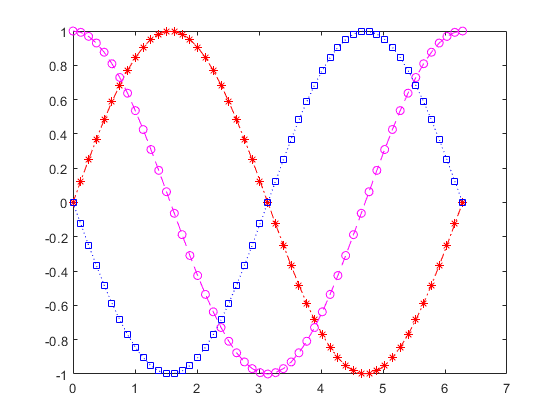

figure
t=0:pi/25:2*pi; %represent the timeline
plot(t,sin(t),'-.r*')
hold on
plot(t,cos(t),'--mo')
plot(t,sin(t-pi),':bs')
hold off

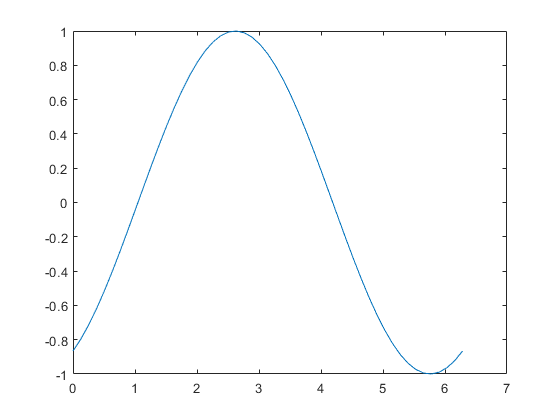

plot(t,sin(t-pi/3))

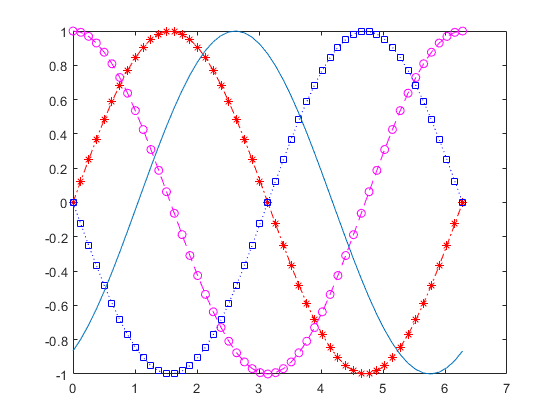

figure
t=0:pi/25:2*pi; %represent the timeline
plot(t,sin(t),'-.r*')
hold on
plot(t,cos(t),'--mo')
plot(t,sin(t-pi),':bs')
%hold off
plot(t,sin(t-pi/3))

example 2

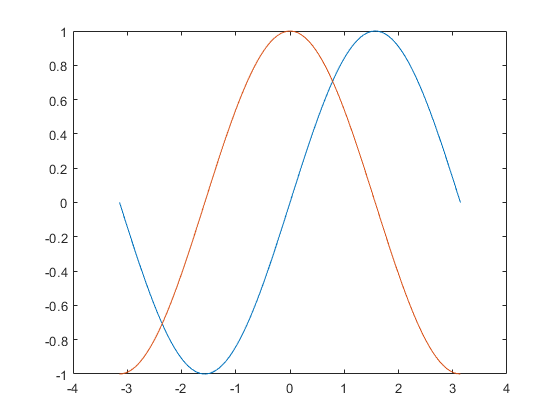

% clear all
% clc
close all
x=linspace(-pi,pi);
y1=sin(x);
y2=cos(x);
plot(x,y1)
hold on
plot(x,y2)
hold off

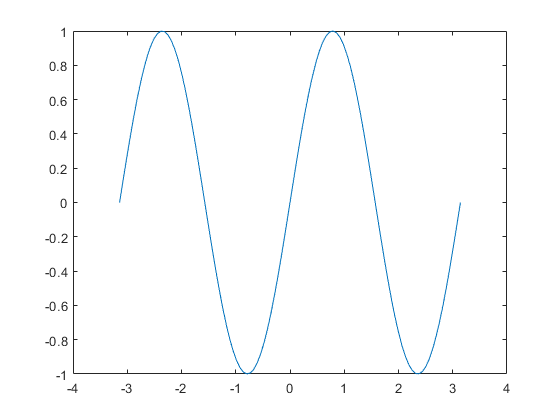

y3=sin(2*x);
plot(x,y3)

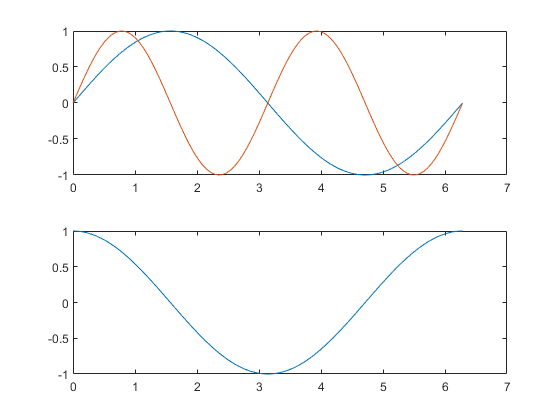

% clear all
% clc
close all
ax1=subplot(2,1,1);
x=linspace(0,2*pi);

y1=sin(x);
plot(x,y1)

ax2=subplot(2,1,2);
y2=cos(x);
plot(x,y2)

hold(ax1,'on');
y3=sin(2*x);

plot(ax1,x,y3)

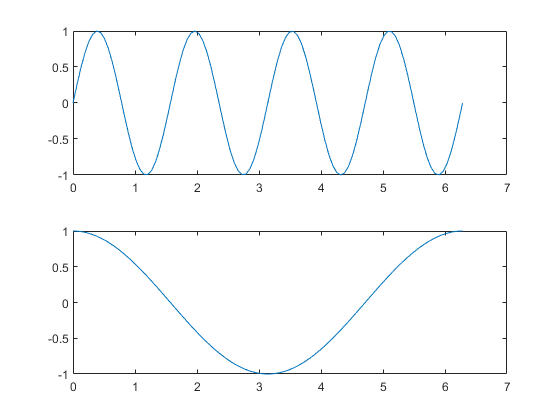

% clear all
% clc
close all
ax1=subplot(2,1,1);
x=linspace(0,2*pi);

y1=sin(x);
plot(x,y1)

ax2=subplot(2,1,2);
y2=cos(x);
plot(x,y2)

hold(ax1,'on');
y3=sin(2*x);

plot(ax1,x,y3)
hold(ax1,'off')

y4=sin(4*x);
plot(ax1,x,y4)

## Graph Properties in Matlab

LineWidth-

MarkerEdgeColor-

MarkerFaceColor-

MarkerSize-

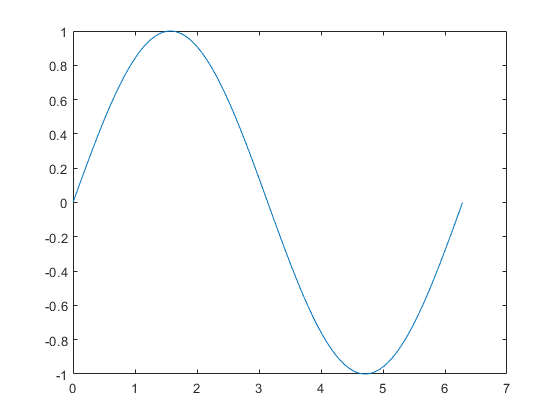

% clear all
% clc
close all
x=linspace(0,2*pi);

y1=sin(x);
plot(x,y1)

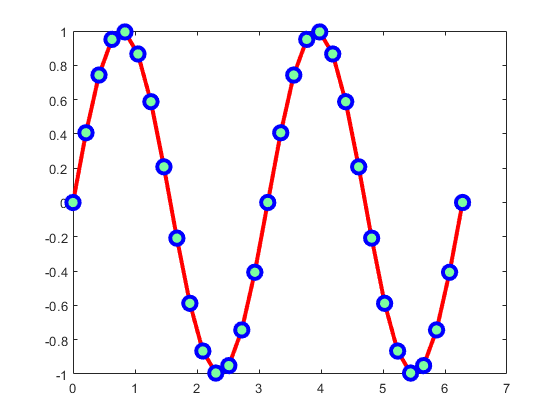

% clear all
% clc
close all
x=0:pi/15:2*pi;

y1=sin(2*x);
plot(x,y1,'-ro','LineWidth',3,...
    'MarkerEdgeColor','b',...
    'MarkerFaceColor',[0.49 1 .63],...
    'MarkerSize',10)

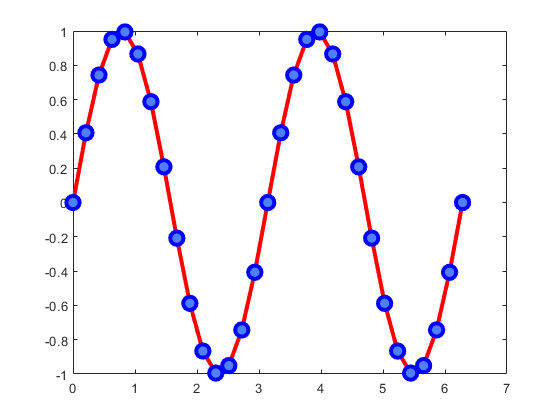

% clear all
% clc
close all
x=0:pi/15:2*pi;

y1=sin(2*x);
plot(x,y1,'-ro','LineWidth',3,...
    'MarkerEdgeColor','b',...
    'MarkerFaceColor',[0.3 0.5 .98],...
    'MarkerSize',10)

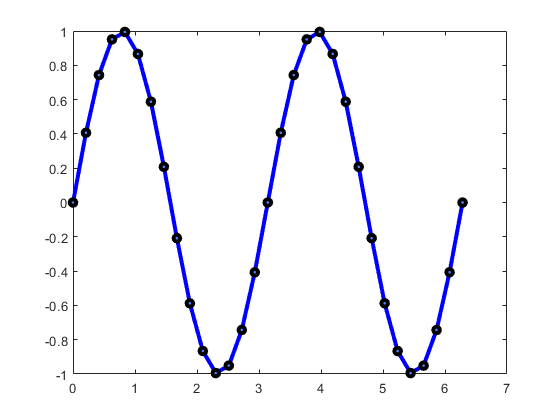


% clear all
% clc
close all
x=0:pi/15:2*pi;

y1=sin(2*x);
plot(x,y1,'-bo','LineWidth',3,...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.3 0.5 .98],...
    'MarkerSize',5)

## work with Axis command in Matlab

example-1

% clear all
% clc
close all
x=linspace(0,2*pi);
y=cos(x);
plot(x,y,'-r')

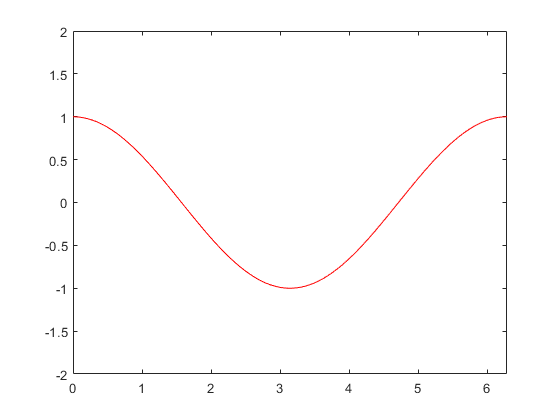

%clear all
% clc
close all
x=linspace(0,2*pi);
y=cos(x);
plot(x,y,'-r')

axis([0 2*pi -2 2])

example-2

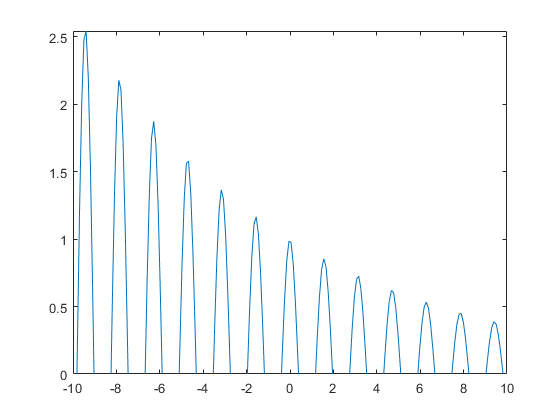

%clear all
% clc
close all
x=linspace(-10,10,200);
y=cos(4*x)./exp(0.1*x);
plot(x,y)
axis([-10 10 0 inf])

clear
close all
x1=linspace(-10,10,200);
y1=sin(x1);
ax1=subplot(2,1,1)

ax1 =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.5838 0.7750 0.3412]
            Units: 'normalized'

  Show all properties


plot(ax1,x1,y1)

x2=linspace(0,5,100);
y2=sin(x2);
ax2=subplot(2,1,2)

ax2 =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.3412]
            Units: 'normalized'

  Show all properties


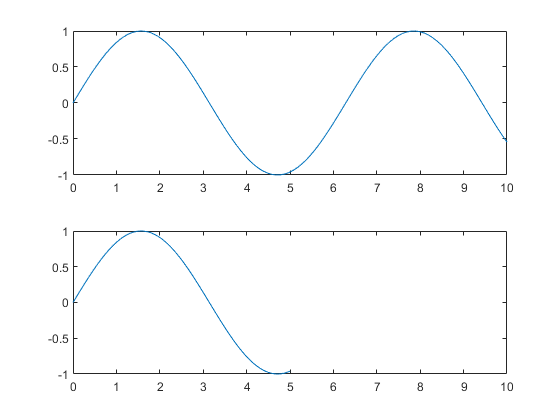

plot(ax2,x2,y2)

axis([ax1,ax2],[0 10 -1 1])

**linkaxes**

clear
close all
x1=linspace(-10,10,200);
y1=sin(x1);
ax1=subplot(2,1,1)

ax1 =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.5838 0.7750 0.3412]
            Units: 'normalized'

  Show all properties


plot(ax1,x1,y1)

x2=linspace(0,5,100);
y2=sin(x2);
ax2=subplot(2,1,2)

ax2 =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.3412]
            Units: 'normalized'

  Show all properties


plot(ax2,x2,y2)

axis([ax1,ax2],[0 10 -1 1])
linkaxes([ax1 ax2],'x')

# **Functions in Matlab**

% % function written in script or function

% function area=areacalc(a)
% %area of square. a is side
% area=a*a;
% fprintf('the area of the square is: %0.2f',area)
% end
areacalc(5)

the area of the square is: 25.00

ans = 25

## Functions with Two Outputs in Matlab

% function [area,circumference]=rect_side(a,b)
% area=a*b;
% circumference=2*(a+b);
% end
[area,circumference]=rect_side(4,5)

area = 20

circumference = 18

## anonymous Functions in Matlab and how to use them

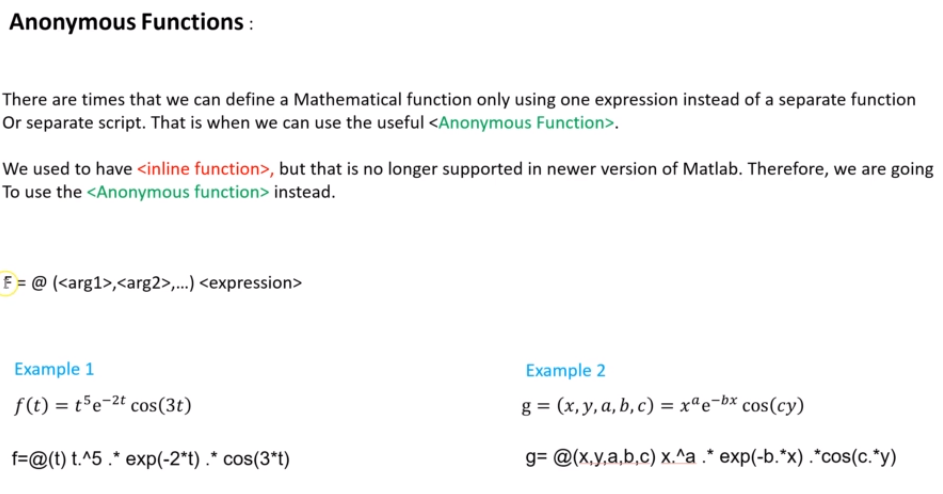

F=@(t)t.^5.*exp(-2*t).*cos(3*t)

F = function_handle with value:
    @(t)t.^5.*exp(-2*t).*cos(3*t)



F(5)

ans = -0.1078

F(1:5)

ans =    -0.1340    0.5628   -0.5488    0.2899   -0.1078


x=[0:0.5:10]'

x =          0
    0.5000
    1.0000
    1.5000
    2.0000
    2.5000
    3.0000
    3.5000
    4.0000
    4.5000


F(x)

ans =          0
    0.0008
   -0.1340
   -0.0797
    0.5628
    0.2281
   -0.5488
   -0.2278
    0.2899
    0.1355


F(-2)

ans = -1.6776e+03

A=rand(6)

A =     0.8147    0.2785    0.9572    0.7922    0.6787    0.7060
    0.9058    0.5469    0.4854    0.9595    0.7577    0.0318
    0.1270    0.9575    0.8003    0.6557    0.7431    0.2769
    0.9134    0.9649    0.1419    0.0357    0.3922    0.0462
    0.6324    0.1576    0.4218    0.8491    0.6555    0.0971
    0.0975    0.9706    0.9157    0.9340    0.1712    0.8235


F(A)

ans =    -0.0539    0.0006   -0.1142   -0.0462   -0.0166   -0.0222
   -0.0908   -0.0011    0.0012   -0.1152   -0.0355    0.0000
    0.0000   -0.1143   -0.0489   -0.0126   -0.0314    0.0006
   -0.0942   -0.1177    0.0000    0.0000    0.0016    0.0000
   -0.0091    0.0001    0.0017   -0.0669   -0.0126    0.0000
    0.0000   -0.1204   -0.0952   -0.1035    0.0001   -0.0571


another type

g=@cos

g = function_handle with value:
    @cos



g(0)

ans = 1

g(pi/2)

ans = 6.1232e-17

g(pi/3)

ans = 0.5000

help heaviside

 heaviside    Step function.
     heaviside(X) is 0 for X < 0 and 1 for X > 0.
     The value heaviside(0) is 0.5 by default. It
     can be changed to any value v by the call 
     sympref('HeavisideAtOrigin', v).
 
     heaviside(X) is not a function in the strict sense.
     See also dirac.

    Reference page for heaviside
    Other functions named heaviside



t=@(x)(heaviside(x+1)-heaviside(x-1)).*(1-abs(x))

t = function_handle with value:
    @(x)(heaviside(x+1)-heaviside(x-1)).*(1-abs(x))



t(1)

ans = 0

t(0.5)

ans = 0.5000

% plot(x,t(x))
% axis([-10,10,-5,5])
t(-1)

ans = 0

ezplot , fplot

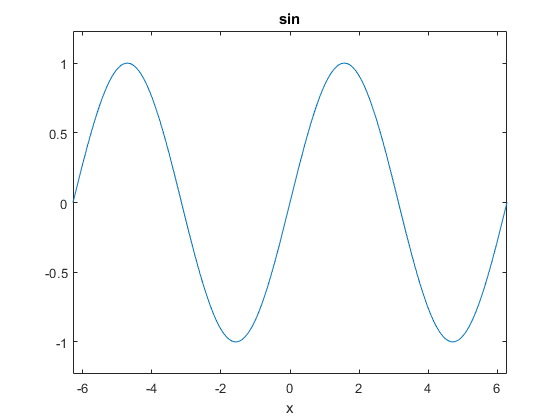

ezplot(@sin)

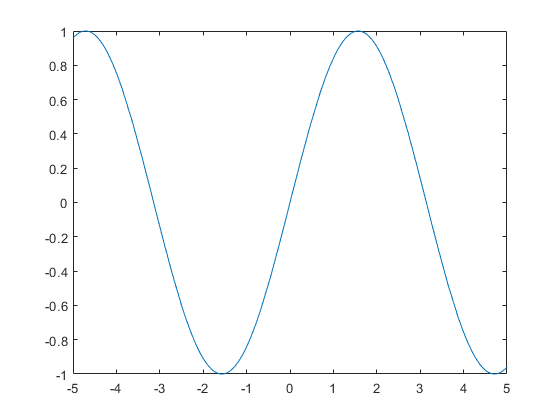

fplot(@sin)

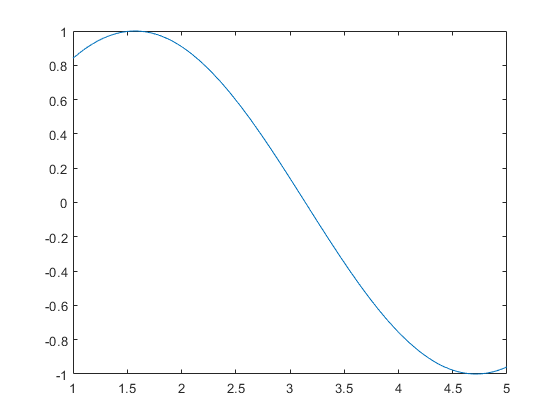

fplot(@sin,[1 5])

# **Logical Statement & Operations in Matlab**

%program to sqrt of entered number
num=input('enter th no.: ')

num = 1.5869e+04

if num>0
    sqr=sqrt(num);
    fprintf('the square root of %0.3f is: %0.4f',num,sqr)
elseif num<0
    num=abs(num);
    sqr=sqrt(num);
    fprintf('the square root of %0.3f is: %0.4f',num,sqr)
else
    fprintf('sqrt of zero is zero')
end

the square root of 15869.223 is: 125.9731

number match program

%odd even
num=input('enter a integer number:')

num = 12

if rem(num, 2)==0
    disp('even')
else
    disp('odd')
end

even


%grade entry program
% clear
% close all
grade=input('enter the grade of the student: ','s')

grade = 'B'

if grade=='A'
    fprintf('student''s grade is %c excellent job\n',grade)
elseif grade=='B'
    fprintf('student''s grade is %c excellent job\n',grade)
elseif grade=='C'
    fprintf('student''s grade is %c well done\n',grade)
elseif grade=='D'
    fprintf('student''s grade is %c try harder\n',grade)
elseif grade=='F'
    fprintf('student''s grade is %c try again\n',grade)
else
    fprintf('invalid input!')
end

student's grade is B excellent job


**switch**() function use 

grade=input('enter the grade of the student: ','s')

grade = 'F'

switch(grade)
    case 'A'
        fprintf('student''s grade is %c excellent job\n',grade)
    case 'B'
        fprintf('student''s grade is %c excellent job\n',grade)
    case 'C'
        fprintf('student''s grade is %c well done\n',grade)
    case 'D'
        fprintf('student''s grade is %c try harder\n',grade)
    case 'F'
        fprintf('student''s grade is %c try again\n',grade)
    otherwise
        fprintf('invalid input!')
end

student's grade is F try again


**Movie Rating Project**

% function review=ratingvalue(rating)
% if rating<0 || rating>5
%     review='invalid entry'
% else
%     switch rating
%         case 5
%             review='5 star'
%         case 4
%             review='4 star'
%         case 3
%             review='3 star'
%         case 2
%             review='2 star'
%         case 1
%             review='1 star'
%         otherwise
%             review='no rating given'
%     end
% 
% end
ratingvalue(3)

review = '3 star'

ans = '3 star'

**menu (GUI selection)**

a pop-up will appear with list of options.

sensor_selection=menu('select the sensor to read data from','Presure sensor',...
    'temperature sensor','Flow sensor')

sensor_selection = 3

if sensor_selection==1
    disp('data is coming from Pressure sensor')
elseif sensor_selection==2
    disp('data is coming from the temperature sensor')
elseif sensor_selection==3
    disp('data is coming from Flow sensor')
else
    disp('no sensor is selected')
end

data is coming from Flow sensor


same program using **switch**

sensor_selection=menu('select the sensor to read data from','Presure sensor',...
    'temperature sensor','Flow sensor')

sensor_selection = 1

switch sensor_selection
    case 1
        disp('data is coming from Pressure sensor')
    case 1
        disp('data is coming from the temperature sensor')
    case 1
        disp('data is coming from Flow sensor')
    otherwise
        disp('no sensor is selected')
end

data is coming from Pressure sensor


# **Project 1 **: Use Matlab Project to build a BMI System Measurement

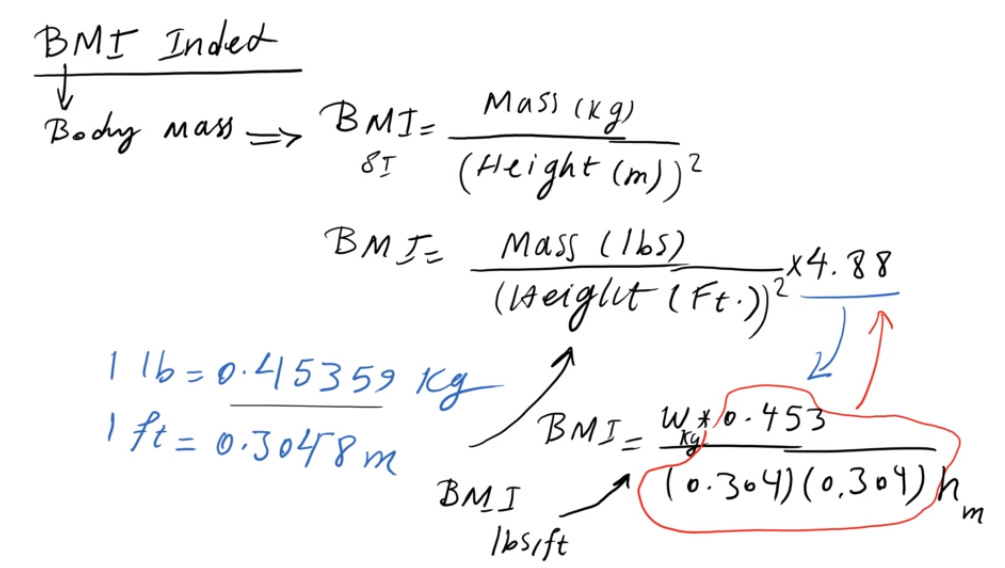

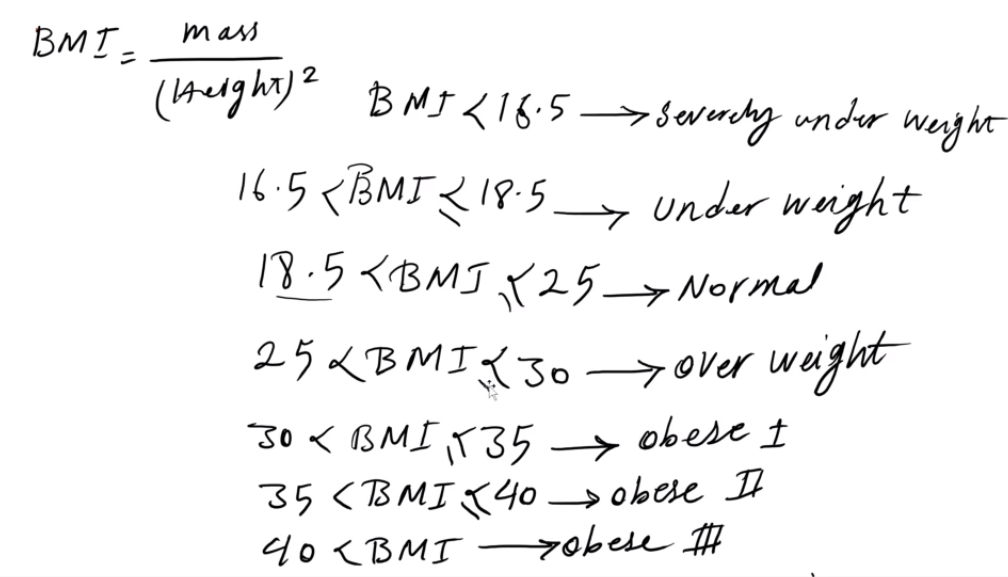

%BMI Calculator
clc;
clear;
close all;
disp('Welcome to the BMI calculator')

Welcome to the BMI calculator


disp('-')

-



unit=menu('unit selection table','Imerial','SI standerd')

unit = 2


if unit==1
    
    fprintf('%s unit of measurement is selected','Imerial')
    disp(' ')
    disp(' ')

    Weight=input('enter your weight(lbs): ')
    Height=input('enter your height(ft):')
    BMI=(Weight/Height^2)*4.88
    
    Wmin=18.5*Height^2*(1/4.88);
    fprintf('your min healthy waight if %0.3f lba',Wmin)
    
    Wmax=25*Height^2*(1/4.88);
    fprintf('your max healthy waight if %0.3f lbs',Wmax)
    
    
    if BMI<16.5
        disp('You are severely underweight, please visit a nutritionist ASAP ')
        disp(' ')
        fprintf('you need to gain min %.2f lbs and max %.2f lbs',Wmin-Weight,Wmax-Weight)
    elseif ((BMI>16.5) && (BMI<18.5))
        disp('You ar underweight, please visit a nutritionist ASAP ')
        disp(' ')
        fprintf('you need to gain min %.2f lbs and max %.2f lbs',Wmin-Weight,Wmax-Weight)
    elseif ((BMI>18.5) && (BMI<25))
        disp('You are Normal ')
        disp(' ')
    elseif ((BMI>25) && (BMI<30))
        disp('You are overweight, please be more active ')
        disp(' ')
        fprintf('you need to lose min %.2f lbs and max %.2f lbs',Weight-Wmax,Weight-Wmin)
    elseif ((BMI>30) && (BMI<35))
        disp('You are obese level-1, please be more active ')
        disp(' ')
        fprintf('you need to lose min %.2f lbs and max %.2f lbs',Weight-Wmax,Weight-Wmin)
    elseif ((BMI>35) && (BMI<40))
        disp('You are obese level-2, please see a doctor ')
        disp(' ')
        fprintf('you need to lose min %.2f lbs and max %.2f lbs',Weight-Wmax,Weight-Wmin)
    elseif (BMI>40)
        disp('You are obese level-3, please see a doctor')
        disp(' ')
        fprintf('you need to lose min %.2f lbs and max %.2f lbs',Weight-Wmax,Weight-Wmin)
           
    end

else
    fprintf('%s unit of measurement is selected','SI')
    disp(' ')
    disp(' ')

    Weight=input('enter your weight(kg): ')
    Height=input('enter your height(m):')
    BMI=(Weight/Height^2)
    
    Wmin=18.5*Height^2;
    fprintf('your min healthy waight if %0.3f kg',Wmin)
    
    Wmax=25*Height^2*(1/4.88);
    fprintf('your max healthy waight if %0.3f kg',Wmax)
    
    
    if BMI<16.5
        disp('You are severely underweight, please visit a nutritionist ASAP ')
        disp(' ')
        fprintf('you need to gain min %.2f kg and max %.2f kg',Wmin-Weight,Wmax-Weight)
    
    elseif ((BMI>16.5) && (BMI<18.5))
        disp('You ar underweight, please visit a nutritionist ASAP ')
        disp(' ')
        fprintf('you need to gain min %.2f kg and max %.2f kg',Wmin-Weight,Wmax-Weight)
    
    elseif ((BMI>18.5) && (BMI<25))
        disp('You are Normal ')
        disp(' ')
    
    elseif ((BMI>25) && (BMI<30))
        disp('You are overweight, please be more active ')
        disp(' ')
        fprintf('you need to lose min %.2f kg and max %.2f kg',Weight-Wmax,Weight-Wmin)
    elseif ((BMI>30) && (BMI<35))
        disp('You are obese level-1, please be more active ')
        disp(' ')
        fprintf('you need to lose min %.2f lbs and max %.2f lbs',Weight-Wmax,Weight-Wmin)
    
    elseif ((BMI>35) && (BMI<40))
        disp('You are obese level-2, please see a doctor ')
        disp(' ')
        fprintf('you need to lose min %.2f kg and max %.2f kg',Weight-Wmax,Weight-Wmin)
    
    elseif (BMI>40)
        disp('You are obese level-3, please see a doctor')
        disp(' ')
        fprintf('you need to lose min %.2f kg and max %.2f kg',Weight-Wmax,Weight-Wmin)
    end
    
end

SI unit of measurement is selected

Weight = 60

Height = 1.5000

BMI = 26.6667

your min healthy waight if 41.625 kg

your max healthy waight if 11.527 kg

You are overweight, please be more active 


you need to lose min 48.47 kg and max 18.38 kg

disp('end of the program')

end of the program


# Project-2 Write a Program to identify the Prime Numbers

floor(3.17)

ans = 3

floor(pi)

ans = 3

help mod

 mod    Modulus after division.
    mod(x,y) returns x - floor(x./y).*y if y ~= 0, carefully computed to
    avoid rounding error. If y is not an integer and the quotient x./y is
    within roundoff error of an integer, then n is that integer. The inputs
    x and y must be real and have compatible sizes. In the simplest cases,
    they can be the same size or one can be a scalar. Two inputs have
    compatible sizes if, for every dimension, the dimension sizes of the
    inputs are either the same or one of them is 1.
 
    The statement "x and y are congruent mod m" means mod(x,m) == mod(y,m).
 
    By convention:
       mod(x,0) is x.
       mod(x,x) is 0.
       mod(x,y), for x~=y and y~=0, has the same sign as y.
 
    Note: REM(x,y), for x~=y and y~=0, has the same sign as x.
    mod(x,y) and REM(x,y) are equal if x and y have the same sign, but
    differ by y if x and y have di

help rem

 rem    Remainder after division.
    rem(x,y) returns x - fix(x./y).*y if y ~= 0, carefully computed to
    avoid rounding error. If y is not an integer and the quotient x./y is
    within roundoff error of an integer, then n is that integer. The inputs
    x and y must be real and have compatible sizes. In the simplest cases,
    they can be the same size or one can be a scalar. Two inputs have
    compatible sizes if, for every dimension, the dimension sizes of the
    inputs are either the same or one of them is 1.
 
    By convention:
       rem(x,0) is NaN.
       rem(x,x), for x~=0, is 0.
       rem(x,y), for x~=y and y~=0, has the same sign as x.
 
    Note: MOD(x,y), for x~=y and y~=0, has the same sign as y.
    rem(x,y) and MOD(x,y) are equal if x and y have the same sign, but
    differ by y if x and y have different signs.
 
    See also mod.


prime=1;
n=input('enter th positive integer: ')

n = 145893331

for i=2:floor(sqrt(n))
    if mod(n,i)==0
        prime=0;
        break;
    end    
end
if prime==1
    fprintf('the %d no is a prime no',n)
else
    fprintf('the %d is not prime no, its one factor is: %d',n,i)
end

the 145893331 is not prime no, its one factor is: 37

We can also define a function as

% function output=check_prime(n)
% prime=1;
% %n=input('enter th positive integer: ')
% for i=2:floor(sqrt(n))
%     if mod(n,i)==0
%         prime=0;
%         break;
%     end    
% end
% if prime==1
%     fprintf('the %d no is a prime no\n',n)
% else
%     fprintf('the %d is not prime no, its one factor is: %d\n',n,i)
% end
% 
% end
check_prime(97)

the 97 no is a prime no


check_prime(121)

the 121 is not prime no, its one factor is: 11


## 2nd method to find prime no.

mod(4,2)

ans = 0

~mod(4,2)

ans = logical
   1



mod(7,5)

ans = 2

~mod(3,2)

ans = logical
   0


N=input('enter th positive integer: ')

N = 25


for a=2:N
    for b=2:N
        if(~mod(a,b))  %if true(1)
            break; %we knoe this is not prime
        end
    end
if (b>(a/b))
    fprintf('%d is a prime no\n',a)
end
end

2 is a prime no
3 is a prime no
5 is a prime no
7 is a prime no
11 is a prime no
13 is a prime no
17 is a prime no
19 is a prime no
23 is a prime no


**tic-toc : shows elapsed time to rum code bitween them**

N=input('enter th positive integer: ')

N = 100


tic

for a=2:N
    for b=2:N
        if(~mod(a,b))  %if true(1)
            break; %we knoe this is not prime
        end
    end
if (b>(a/b))
    fprintf('%d is a prime no\n',a)
end
end

2 is a prime no
3 is a prime no
5 is a prime no
7 is a prime no
11 is a prime no
13 is a prime no
17 is a prime no
19 is a prime no
23 is a prime no
29 is a prime no
31 is a prime no
37 is a prime no
41 is a prime no
43 is a prime no
47 is a prime no
53 is a prime no
59 is a prime no
61 is a prime no
67 is a prime no
71 is a prime no
73 is a prime no
79 is a prime no
83 is a prime no
89 is a prime no
97 is a prime no



toc

Elapsed time is 0.044851 seconds.


*** END ***